## Initialize Directory

defaultDir = 'M:\Projects And Analysis\Papers\P2ry1'; %change if in a different location
cd(defaultDir);
addpath(genpath('MATLAB Functions'));
cd('Figure 1 - Gq Pharm and P2ry1 Expression');


%load Pharm Data
fileList = loadFileList('.\Data\Han Chin\ISC*\*\*gfv_stats.mat');
cells = struct([]);
for i = 1:size(fileList,1)
    load(fileList{i});
    if i == 1
        cells= struct(tempCell);
    else
        cells(i) = tempCell;
    end
end

condNum =  unique({cells.condition})

condNum = 1×5 cell array
    {'BAPTA-AM'}    {'DMSO Control'}    {'Thapsigargin'}    {'U73122'}    {'U73343'}


for i = 1:size(condNum,2)
    index = find(contains({cells.condition},condNum{i}))
    tempPks = []; tempMeans = []; tempInts = [];
    for j = 1:size(index,2)
        tempPks(j)= cells(index(j)).stats.numPeaks;
        tempMeans(j) = cells(index(j)).stats.meanAmp;
        tempInts(j) = cells(index(j)).stats.integral;
    end
    peaks{i} = tempPks;
    means{i} = tempMeans;
    ints{i} = tempInts;
end

index =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16


index =     17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32


index =     33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51    52


index =     53    54    55    56    57    58    59    60    61    62    63    64    65    66


index =     67    68    69    70    71    72    73    74    75    76    77    78    79    80    81    82



peaks = {peaks{2} peaks{1} peaks{3} peaks{4} peaks{5}};
means = {means{2} means{1} means{3} means{4} means{5}};
ints = {ints{2} ints{1} ints{3} ints{4} ints{5}};
condNum = {condNum{2} condNum{1} condNum{3} condNum{4} condNum{5}};

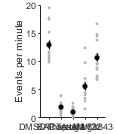

dim = [1.2 1.4];
[h] = compare5(peaks{1}/10, peaks{2}/10,peaks{3}/10, peaks{4}/10, peaks{5}/10, condNum, 'Events per minute', dim,[5 12]);
figure(h);
ylim([0 20]);
yticks(0:5:20);
export_fig('.\EPS Panels\inhibitors_freq.eps');

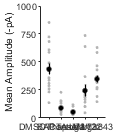

h = compare5(means{1}, means{2}, means{3}, means{4}, means{5}, condNum, 'Mean Amplitude (-pA)', dim,[5 12]);
figure(h);
ylim([0 1000]);
yticks([0:250:1000]);
export_fig('.\EPS Panels\inhibitors_amps.eps');

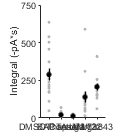

h = compare5(ints{1}/600, ints{2}/600,ints{3}/600, ints{4}/600,ints{5}/600, condNum, 'Integral (-pA*s)', dim,[5 12]);
figure(h);
ylim([0 750]);
yticks([0:250:750]);
export_fig('.\EPS Panels\inhibitors_ints.eps');

# Crenations

%data
Confiles = loadFileList('.\Data\Han Chin\Cren Control\*.mat');
BAPTAfiles = loadFileList('.\Data\Han Chin\Cren BAPTA-AM\*.mat');
Thapsifiles = loadFileList('.\Data\Han Chin\Cren Thapsigargin\*.mat');
U73122files = loadFileList('.\Data\Han Chin\Cren U73122\*.mat');
U73343files = loadFileList('.\Data\Han Chin\Cren U73343\*.mat');

WTareas = []; BAPTAareas = []; Thapsiareas = []; U73122areas = []; U73343areas = [];
WTdata = table();
%load data and analyze
for i = 1:size(Confiles,1)
    load(Confiles{i})
    WTdata = [WTdata; {Crens.name mean(Crens.areas) size(Crens.locs([Crens.areas] > 500),1)/10}];
    WTareas = [WTareas; Crens.areas];
end
WTdata.Properties.VariableNames = {'Filename','CrenArea','CrenFreq'};

BAPTAdata = table();
for i = 1:size(BAPTAfiles,1)
    load(BAPTAfiles{i})
    BAPTAdata = [BAPTAdata; {Crens.name mean(Crens.areas) size(Crens.locs([Crens.areas] > 500),1)/10}];
    BAPTAareas = [BAPTAareas; Crens.areas];
end
BAPTAdata.Properties.VariableNames = {'Filename','CrenArea','CrenFreq'};

Thapsidata = table();
for i = 1:size(Thapsifiles,1)
    load(Thapsifiles{i})
    Thapsidata = [Thapsidata; {Crens.name mean(Crens.areas) size(Crens.locs([Crens.areas] > 500),1)/10}];
    Thapsiareas = [Thapsiareas; Crens.areas];
end
Thapsidata.Properties.VariableNames = {'Filename','CrenArea','CrenFreq'};

U73122data = table();
for i = 1:size(U73122files,1)
    load(U73122files{i})
    U73122data = [U73122data; {Crens.name mean(Crens.areas) size(Crens.locs([Crens.areas] > 500),1)/10}];
    U73122areas = [U73122areas; Crens.areas];
end
U73122data.Properties.VariableNames = {'Filename','CrenArea','CrenFreq'};

U73343data = table();
for i = 1:size(U73343files,1)
    load(U73343files{i})
    U73343data = [U73343data; {Crens.name mean(Crens.areas) size(Crens.locs([Crens.areas] > 500),1)/10}];
    U73343areas = [U73122areas; Crens.areas];
end
U73343data.Properties.VariableNames = {'Filename','CrenArea','CrenFreq'};




## Plot data

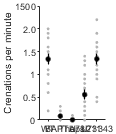

dim = [1.2 1.4];

[h, p] = compare5(WTdata.CrenFreq, BAPTAdata.CrenFreq, Thapsidata.CrenFreq, U73122data.CrenFreq, U73343data.CrenFreq, {'WT', 'BAPTA','Thapsi','U73211','U73343'},'Crenations per minute', dim,[5 12]);
figure(h)
ylim([0 2.5])
yticks([0:0.5:2.5])
yticklabels({'0','0.5','1','1.5','2.0','1500'})
figQuality(gcf, gca, dim);
export_fig('.\EPS Panels\CrenFreq.eps',gcf);

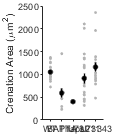


[h, p] = compare5(WTdata.CrenArea, BAPTAdata.CrenArea,Thapsidata.CrenArea, U73122data.CrenArea, U73343data.CrenArea, {'WT', 'BAPTA','Thapsi','U73211','U73343'}, 'Crenation Area (\mum^2)', dim,[5 12]);
figure(h)
ylim([0 2500]);
yticks([0:500:2500]);
figQuality(gcf, gca, dim);
set(gca,'LooseInset',get(gca,'TightInset')) ;

%export_fig('.\EPS Panels\CrenArea.eps',gcf);


%stats
block = getBlock({WTdata.CrenFreq', BAPTAdata.CrenFreq', Thapsidata.CrenFreq', U73122data.CrenFreq', U73343data.CrenFreq'});

temp =     1.5000    1.0000
    1.1000    1.0000
    1.5000    1.0000
    1.1000    1.0000
    0.8000    1.0000
    1.8000    1.0000
    1.9000    1.0000
    1.6000    1.0000
    2.0000    1.0000
    1.0000    1.0000


stBlck =     1.5000    1.0000
    1.1000    1.0000
    1.5000    1.0000
    1.1000    1.0000
    0.8000    1.0000
    1.8000    1.0000
    1.9000    1.0000
    1.6000    1.0000
    2.0000    1.0000
    1.0000    1.0000


temp =     0.2000    2.0000
    0.3000    2.0000
         0    2.0000
    0.3000    2.0000
         0    2.0000
         0    2.0000
    0.2000    2.0000
    0.2000    2.0000
         0    2.0000
         0    2.0000


stBlck =     1.5000    1.0000
    1.1000    1.0000
    1.5000    1.0000
    1.1000    1.0000
    0.8000    1.0000
    1.8000    1.0000
    1.9000    1.0000
    1.6000    1.0000
    2.0000    1.0000
    1.0000    1.0000


temp =      0     3
     0     3
     0     3
     0     3
     0     3
     0     3
     0     3
     0     3
     0     3
     0     3


stBlck =     1.5000    1.0000
    1.1000    1.0000
    1.5000    1.0000
    1.1000    1.0000
    0.8000    1.0000
    1.8000    1.0000
    1.9000    1.0000
    1.6000    1.0000
    2.0000    1.0000
    1.0000    1.0000


temp =     0.1000    4.0000
         0    4.0000
    0.3000    4.0000
         0    4.0000
    1.0000    4.0000
    0.2000    4.0000
    1.4000    4.0000
    1.4000    4.0000
         0    4.0000
    0.4000    4.0000


stBlck =     1.5000    1.0000
    1.1000    1.0000
    1.5000    1.0000
    1.1000    1.0000
    0.8000    1.0000
    1.8000    1.0000
    1.9000    1.0000
    1.6000    1.0000
    2.0000    1.0000
    1.0000    1.0000


temp =     2.6000    5.0000
    1.9000    5.0000
    0.5000    5.0000
    0.9000    5.0000
    1.4000    5.0000
    2.2000    5.0000
    1.0000    5.0000
    0.4000    5.0000
    1.2000    5.0000
    1.6000    5.0000


stBlck =     1.5000    1.0000
    1.1000    1.0000
    1.5000    1.0000
    1.1000    1.0000
    0.8000    1.0000
    1.8000    1.0000
    1.9000    1.0000
    1.6000    1.0000
    2.0000    1.0000
    1.0000    1.0000


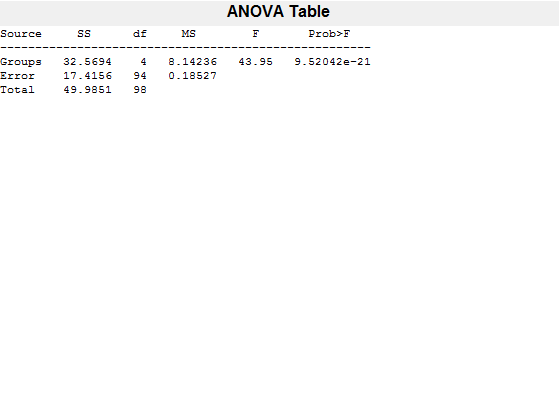

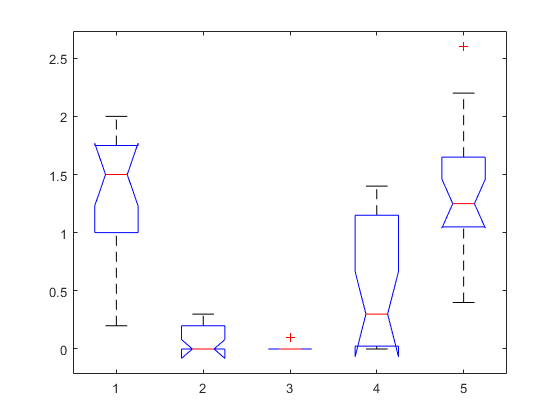

[p,~,stats] = anova1(block(:,1),block(:,2));

 [c] = multcompare(stats,'display','off')

c =     1.0000    2.0000    0.8367    1.2502    1.6637    0.0000
    1.0000    3.0000    0.9573    1.3323    1.7073    0.0000
    1.0000    4.0000    0.4092    0.7803    1.1515    0.0000
    1.0000    5.0000   -0.3867   -0.0032    0.3804    1.0000
    2.0000    3.0000   -0.3188    0.0821    0.4830    0.9791
    2.0000    4.0000   -0.8672   -0.4699   -0.0725    0.0121
    2.0000    5.0000   -1.6623   -1.2533   -0.8444    0.0000
    3.0000    4.0000   -0.9090   -0.5520   -0.1949    0.0004
    3.0000    5.0000   -1.7053   -1.3355   -0.9656    0.0000
    4.0000    5.0000   -1.1495   -0.7835   -0.4174    0.0000


%Example traces
lims = [-2500 100];
dim = [2.5 0.75];
DMSOfile = '.\Data\Han Chin\ISC DMSO Control\120516_Cell7\2012_05_16_0015_gfv.abf';
[d,time] = loadPclampData(DMSOfile);

opening .\Data\Han Chin\ISC DMSO Control\120516_Cell7\2012_05_16_0015_gfv.abf..
**** available channels:
    'IN 0'
    'IN 1'
    'IN 2'

data were acquired in gap-free mode
total length of recording: 600.0 s ~ 10 min
sampling interval: 99 µs
memory requirement for complete upload in matlab: 139 MB


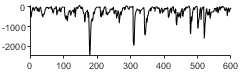

d = d(:,1);
out = msbackadj(time, -d, 'WindowSize', 60,'StepSize',60);
figure;
plot(time,-out,'k');
ylim(lims);
figQuality(gcf,gca,dim);
export_fig('.\EPS Panels\control_trace.eps')


BAPTAfile = '.\Data\Han Chin\ISC BAPTA-AM\120522_Cell9\2012_05_22_0017_gfv.abf';
[d,time] = loadPclampData(BAPTAfile);

opening .\Data\Han Chin\ISC BAPTA-AM\120522_Cell9\2012_05_22_0017_gfv.abf..
**** available channels:
    'IN 0'
    'IN 1'
    'IN 2'

data were acquired in gap-free mode
total length of recording: 600.0 s ~ 10 min
sampling interval: 99 µs
memory requirement for complete upload in matlab: 139 MB


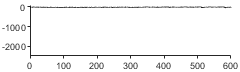

d = d(:,1);
out = msbackadj(time, -d, 'WindowSize', 60,'StepSize',60);
figure;
plot(time,-out,'k');
ylim(lims);
figQuality(gcf,gca,dim);
export_fig('.\EPS Panels\BAPTA_trace.eps')


Thapsifile = '.\Data\Han Chin\ISC Thapsigargin\120531_Cell4\2012_05_31_0009_gfv.abf';
[d,time] = loadPclampData(Thapsifile);

opening .\Data\Han Chin\ISC Thapsigargin\120531_Cell4\2012_05_31_0009_gfv.abf..
**** available channels:
    'IN 0'
    'IN 1'
    'IN 2'

data were acquired in gap-free mode
total length of recording: 600.0 s ~ 10 min
sampling interval: 99 µs
memory requirement for complete upload in matlab: 139 MB


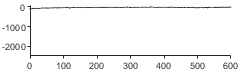

d = d(:,1);
out = msbackadj(time, -d, 'WindowSize', 60,'StepSize',60);
figure;
plot(time,-out,'k');
ylim(lims);
figQuality(gcf,gca,dim);
export_fig('.\EPS Panels\Thapsi_trace.eps')


PLCfile = '.\Data\Han Chin\ISC U73122\120622_Cell1\2012_06_22_0000_gfv.abf';
[d,time] = loadPclampData(PLCfile);

opening .\Data\Han Chin\ISC U73122\120622_Cell1\2012_06_22_0000_gfv.abf..
**** available channels:
    'IN 0'
    'IN 1'
    'IN 2'

data were acquired in gap-free mode
total length of recording: 600.0 s ~ 10 min
sampling interval: 99 µs
memory requirement for complete upload in matlab: 139 MB


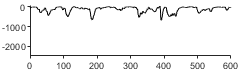

d = d(:,1);
out = msbackadj(time, -d, 'WindowSize', 60,'StepSize',60);
figure;
plot(time,-out,'k');
ylim(lims);
figQuality(gcf,gca,dim);
export_fig('.\EPS Panels\PLC_trace.eps')

## ANOVA analysis

 block = getBlock(peaks);

temp =    100     1
   102     1
   130     1
   177     1
   152     1
   107     1
   175     1
   129     1
   110     1
   115     1


stBlck =    100     1
   102     1
   130     1
   177     1
   152     1
   107     1
   175     1
   129     1
   110     1
   115     1


temp =     18     2
    19     2
    20     2
    21     2
    15     2
    23     2
    11     2
    39     2
    10     2
     4     2


stBlck =    100     1
   102     1
   130     1
   177     1
   152     1
   107     1
   175     1
   129     1
   110     1
   115     1


temp =      6     3
     5     3
     5     3
    26     3
     2     3
     9     3
     5     3
    11     3
    19     3
     3     3


stBlck =    100     1
   102     1
   130     1
   177     1
   152     1
   107     1
   175     1
   129     1
   110     1
   115     1


temp =     16     4
    41     4
   124     4
    52     4
    30     4
    45     4
    57     4
    35     4
    58     4
    70     4


stBlck =    100     1
   102     1
   130     1
   177     1
   152     1
   107     1
   175     1
   129     1
   110     1
   115     1


temp =     71     5
    96     5
   107     5
   109     5
   148     5
   145     5
    75     5
    68     5
    97     5
   167     5


stBlck =    100     1
   102     1
   130     1
   177     1
   152     1
   107     1
   175     1
   129     1
   110     1
   115     1


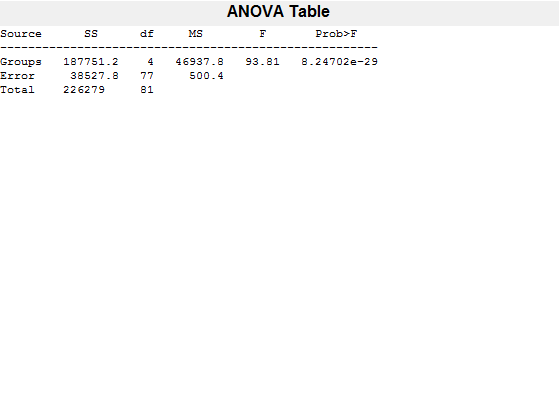

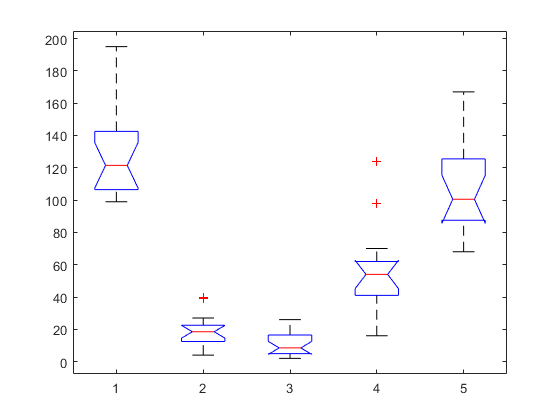

[p,~,stats] = anova1(block(:,1),block(:,2));

 [c] = multcompare(stats,'display','off')

c =     1.0000    2.0000   88.2202  110.3125  132.4048    0.0000
    1.0000    3.0000   98.0539  119.0125  139.9711    0.0000
    1.0000    4.0000   50.6234   73.4911   96.3588    0.0000
    1.0000    5.0000    0.7202   22.8125   44.9048    0.0395
    2.0000    3.0000  -12.2586    8.7000   29.6586    0.7741
    2.0000    4.0000  -59.6891  -36.8214  -13.9537    0.0002
    2.0000    5.0000 -109.5923  -87.5000  -65.4077    0.0000
    3.0000    4.0000  -67.2958  -45.5214  -23.7470    0.0000
    3.0000    5.0000 -117.1586  -96.2000  -75.2414    0.0000
    4.0000    5.0000  -73.5463  -50.6786  -27.8109    0.0000


 
 block = getBlock(means);

temp =   682.5948    1.0000
  608.6589    1.0000
  444.6106    1.0000
  853.0229    1.0000
  723.5889    1.0000
  232.6864    1.0000
  260.1401    1.0000
  360.1872    1.0000
  310.0542    1.0000
  309.4960    1.0000


stBlck =   682.5948    1.0000
  608.6589    1.0000
  444.6106    1.0000
  853.0229    1.0000
  723.5889    1.0000
  232.6864    1.0000
  260.1401    1.0000
  360.1872    1.0000
  310.0542    1.0000
  309.4960    1.0000


temp =    61.9645    2.0000
   66.0445    2.0000
   61.4608    2.0000
  145.9854    2.0000
   58.5642    2.0000
  101.5064    2.0000
   57.1919    2.0000
  131.3943    2.0000
   59.9104    2.0000
   58.5319    2.0000


stBlck =   682.5948    1.0000
  608.6589    1.0000
  444.6106    1.0000
  853.0229    1.0000
  723.5889    1.0000
  232.6864    1.0000
  260.1401    1.0000
  360.1872    1.0000
  310.0542    1.0000
  309.4960    1.0000


temp =    54.2316    3.0000
   30.7942    3.0000
   46.8015    3.0000
   52.9949    3.0000
   40.2248    3.0000
   44.9104    3.0000
   62.4650    3.0000
   51.6422    3.0000
   62.4518    3.0000
   42.6985    3.0000


stBlck =   682.5948    1.0000
  608.6589    1.0000
  444.6106    1.0000
  853.0229    1.0000
  723.5889    1.0000
  232.6864    1.0000
  260.1401    1.0000
  360.1872    1.0000
  310.0542    1.0000
  309.4960    1.0000


temp =    46.2476    4.0000
  104.1902    4.0000
  215.8756    4.0000
  198.3606    4.0000
  101.2400    4.0000
  102.5765    4.0000
  164.4163    4.0000
  185.1186    4.0000
  141.1197    4.0000
  181.9322    4.0000


stBlck =   682.5948    1.0000
  608.6589    1.0000
  444.6106    1.0000
  853.0229    1.0000
  723.5889    1.0000
  232.6864    1.0000
  260.1401    1.0000
  360.1872    1.0000
  310.0542    1.0000
  309.4960    1.0000


temp =   145.9589    5.0000
  429.5722    5.0000
  318.8589    5.0000
  315.3248    5.0000
  366.2476    5.0000
  350.4652    5.0000
  367.7239    5.0000
  273.0002    5.0000
  263.8885    5.0000
  584.8967    5.0000


stBlck =   682.5948    1.0000
  608.6589    1.0000
  444.6106    1.0000
  853.0229    1.0000
  723.5889    1.0000
  232.6864    1.0000
  260.1401    1.0000
  360.1872    1.0000
  310.0542    1.0000
  309.4960    1.0000


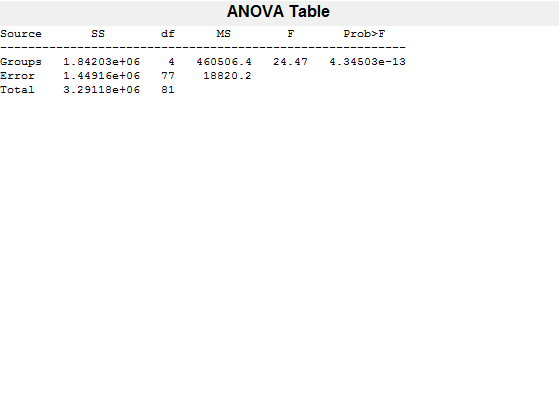

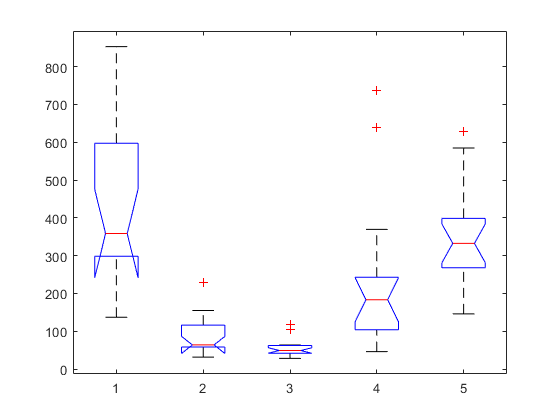

 [p,~,stats] = anova1(block(:,1),block(:,2));

 [c1] = multcompare(stats,'display','off')

c1 =     1.0000    2.0000  210.8158  346.3070  481.7983    0.0000
    1.0000    3.0000  253.9155  382.4538  510.9921    0.0000
    1.0000    4.0000   51.3050  191.5517  331.7985    0.0025
    1.0000    5.0000  -47.8677   87.6235  223.1148    0.3773
    2.0000    3.0000  -92.3915   36.1467  164.6850    0.9341
    2.0000    4.0000 -295.0021 -154.7553  -14.5085    0.0232
    2.0000    5.0000 -394.1747 -258.6835 -123.1923    0.0000
    3.0000    4.0000 -324.4437 -190.9020  -57.3604    0.0014
    3.0000    5.0000 -423.3685 -294.8303 -166.2920    0.0000
    4.0000    5.0000 -244.1750 -103.9282   36.3186    0.2436


 
 block = getBlock(ints)

temp = 	1.0e+05 *

    3.2333    0.0000
    2.7455    0.0000
    1.4349    0.0000
    3.8112    0.0000
    3.0194    0.0000
    0.6634    0.0000
    1.5546    0.0000
    1.2409    0.0000
    1.0560    0.0000
    1.0561    0.0000


stBlck = 	1.0e+05 *

    3.2333    0.0000
    2.7455    0.0000
    1.4349    0.0000
    3.8112    0.0000
    3.0194    0.0000
    0.6634    0.0000
    1.5546    0.0000
    1.2409    0.0000
    1.0560    0.0000
    1.0561    0.0000


temp = 	1.0e+04 *

    1.5803    0.0002
    0.6460    0.0002
    0.6991    0.0002
    0.5695    0.0002
    0.6953    0.0002
    1.1831    0.0002
    0.7808    0.0002
    1.9634    0.0002
    0.6252    0.0002
    0.7416    0.0002


stBlck = 	1.0e+05 *

    3.2333    0.0000
    2.7455    0.0000
    1.4349    0.0000
    3.8112    0.0000
    3.0194    0.0000
    0.6634    0.0000
    1.5546    0.0000
    1.2409    0.0000
    1.0560    0.0000
    1.0561    0.0000


temp = 	1.0e+04 *

    0.3541    0.0003
    0.5210    0.0003
    0.7466    0.0003
    0.8098    0.0003
    0.3353    0.0003
    0.5855    0.0003
    1.6015    0.0003
    1.5548    0.0003
    1.0439    0.0003
    1.2915    0.0003


stBlck = 	1.0e+05 *

    3.2333    0.0000
    2.7455    0.0000
    1.4349    0.0000
    3.8112    0.0000
    3.0194    0.0000
    0.6634    0.0000
    1.5546    0.0000
    1.2409    0.0000
    1.0560    0.0000
    1.0561    0.0000


temp = 	1.0e+05 *

    0.0936    0.0000
    0.3265    0.0000
    0.8540    0.0000
    0.5883    0.0000
    0.2674    0.0000
    0.3957    0.0000
    0.5234    0.0000
    0.5119    0.0000
    0.3872    0.0000
    0.6686    0.0000


stBlck = 	1.0e+05 *

    3.2333    0.0000
    2.7455    0.0000
    1.4349    0.0000
    3.8112    0.0000
    3.0194    0.0000
    0.6634    0.0000
    1.5546    0.0000
    1.2409    0.0000
    1.0560    0.0000
    1.0561    0.0000


temp = 	1.0e+05 *

    0.3700    0.0001
    1.5382    0.0001
    0.9509    0.0001
    0.9400    0.0001
    1.1953    0.0001
    1.3011    0.0001
    1.3001    0.0001
    0.8895    0.0001
    1.0695    0.0001
    2.4481    0.0001


stBlck = 	1.0e+05 *

    3.2333    0.0000
    2.7455    0.0000
    1.4349    0.0000
    3.8112    0.0000
    3.0194    0.0000
    0.6634    0.0000
    1.5546    0.0000
    1.2409    0.0000
    1.0560    0.0000
    1.0561    0.0000


block = 	1.0e+05 *

    3.2333    0.0000
    2.7455    0.0000
    1.4349    0.0000
    3.8112    0.0000
    3.0194    0.0000
    0.6634    0.0000
    1.5546    0.0000
    1.2409    0.0000
    1.0560    0.0000
    1.0561    0.0000


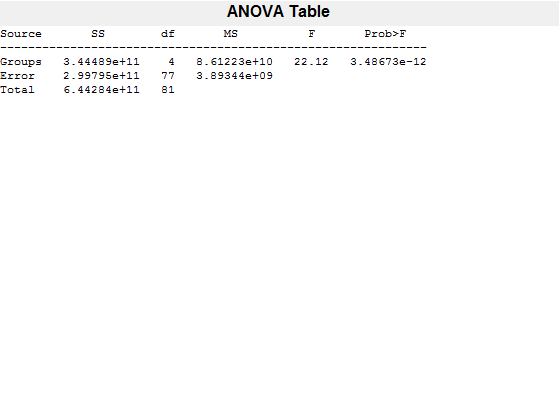

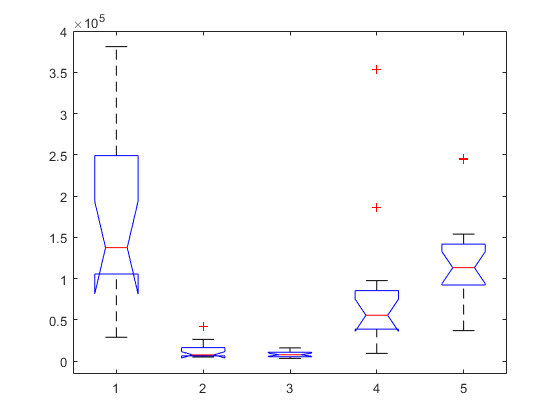

 [p,~,stats] = anova1(block(:,1),block(:,2));

 [c2] = multcompare(stats,'display','off')

c2 = 	1.0e+05 *

    0.0000    0.0000    0.9873    1.6035    2.2198    0.0000
    0.0000    0.0000    1.0633    1.6480    2.2326    0.0000
    0.0000    0.0000    0.2552    0.8931    1.5310    0.0000
    0.0000    0.0001   -0.1272    0.4890    1.1053    0.0000
    0.0000    0.0000   -0.5402    0.0444    0.6290    0.0000
    0.0000    0.0000   -1.3483   -0.7105   -0.0726    0.0000
    0.0000    0.0001   -1.7308   -1.1145   -0.4983    0.0000
    0.0000    0.0000   -1.3623   -0.7549   -0.1475    0.0000
    0.0000    0.0001   -1.7436   -1.1589   -0.5743    0.0000
    0.0000    0.0001   -1.0420   -0.4041    0.2338    0.0000


GFPp =    169    15    15     0


GFPn =         1742          32          10           1


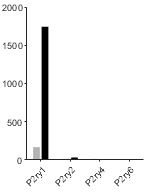

function stBlck = getBlock(cellBlock)
    stBlck = [];
    for i = 1:size(cellBlock,2)
        temp = cellBlock{i};
        temp = [temp' i*ones(size(temp'))]
        stBlck = [stBlck; temp]
    end
end